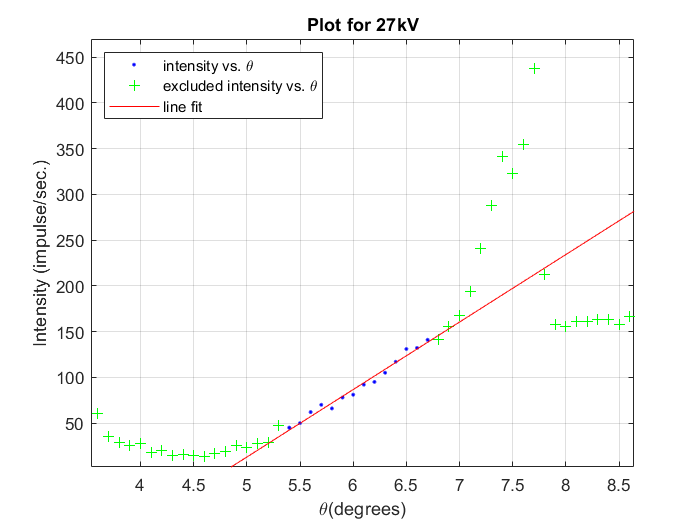

%% Fit: '24kv'.
[xData, yData] = prepareCurveData( theta27kV, Rateat27kV );

% Set up fittype and options.
ft = fittype( 'poly1' );
excludedPoints = excludedata( xData, yData, 'Indices', [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64] );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', '24kv' );
h = plot( fitresult, xData, yData, excludedPoints );
legend( h, 'Rateat27kV vs. theta27kV', 'Excluded Rateat27kV vs. theta27kV', '24kv', 'Location', 'NorthEast' );
% Label axes
legend({'intensity vs. \theta','excluded intensity vs. \theta','line fit'},'Location','northwest')
title('Plot for 27kV')
xlabel('\theta(degrees)')
ylabel('Intensity (impulse/sec.)')
grid on

xlim([3.53 8.64])
ylim([2 470])




%Linear model Poly1:
%     f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =       73.78  (67.14, 80.42)
  %     p2 =        -356  (-396.2, -315.8)

%Goodness of fit:
 % SSE: 253.2
 % R-square: 0.98
 % Adjusted R-square: 0.9783
  % RMSE: 4.594
  % \theta_{min}=4.825 \pm 0.348